# Comparison between EMS

## Get current folder and add all folders to the path

currentpath = pwd;
currentfolder = strsplit(currentpath,filesep);
while ((~strcmp(currentfolder{end}, 'EMS-aircraft')) && ...
    (~strcmp(currentfolder{end}, 'EMS-aircraft-main')) && ...
    ~isempty(currentfolder{end}))
    currentpath = fileparts(currentpath);
    currentfolder = strsplit(currentpath,filesep);
end
projectpath = currentpath;
addpath(genpath(projectpath))

## Get the data folder

folder_data = strcat(projectpath,'\Data\');

## Get local data (faster than below)

PI.out = outPI;
SMC.out = outSMC;
FUZZY.out = outFUZZY;
ECMS.out = outECMS;

EMS_sim = [PI;SMC;FUZZY;ECMS];

## Get the stored data from data file


% tic
% PI = load(strcat(folder_data,'PI_300.mat'));
% SMC = load(strcat(folder_data,'SMC_300.mat'));
% FUZZY = load(strcat(folder_data,'FUZZY_300.mat'));
% toc

% tic
% PI = load(strcat(folder_data,'B20_PI_300.mat'));
% SMC = load(strcat(folder_data,'B20_SMC_300.mat'));
% FUZZY = load(strcat(folder_data,'B20_FUZZY_300.mat'));
% toc

% tic
% PI = load(strcat(folder_data,'B80_PI_85.mat'));
% SMC = load(strcat(folder_data,'B80_SMC_85.mat'));
% FUZZY = load(strcat(folder_data,'B80_FUZZY_85.mat'));
% toc

% tic
% PI = load(strcat(folder_data,'B80_PI_85.mat'));
% SMC = load(strcat(folder_data,'B80_SMC_85.mat'));
% FUZZY = load(strcat(folder_data,'B80_FUZZY_85.mat'));
% ECMS = load(strcat(folder_data,'B80_ECMS_85.mat'));
% toc

# Curves

## Voltage

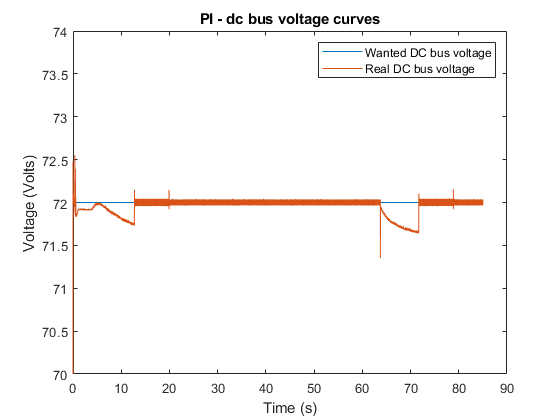

tic
bus_curve(PI,'PI');

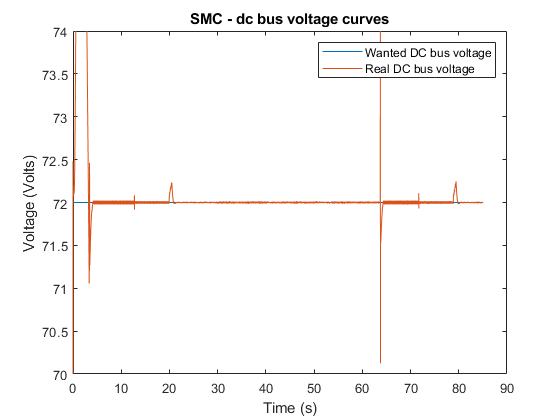

bus_curve(SMC,'SMC');

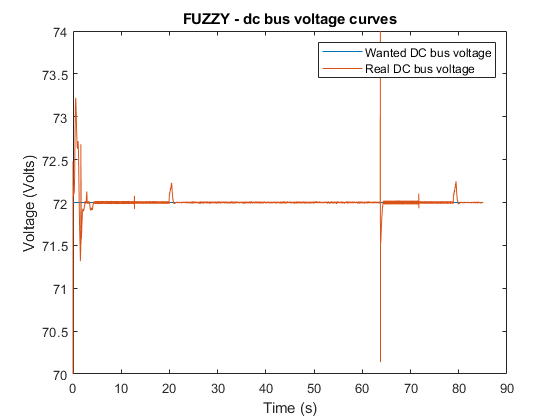

bus_curve(FUZZY,'FUZZY');

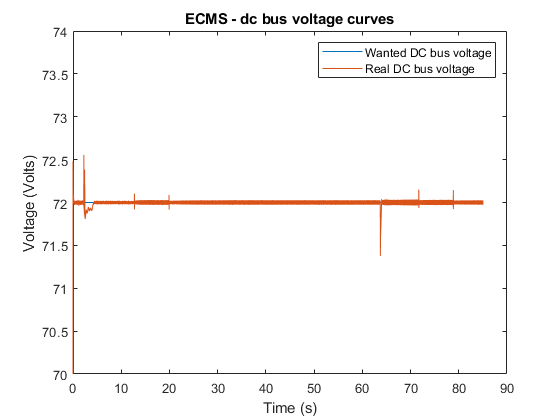

bus_curve(ECMS,'ECMS');

toc

Elapsed time is 3.876747 seconds.


## Power

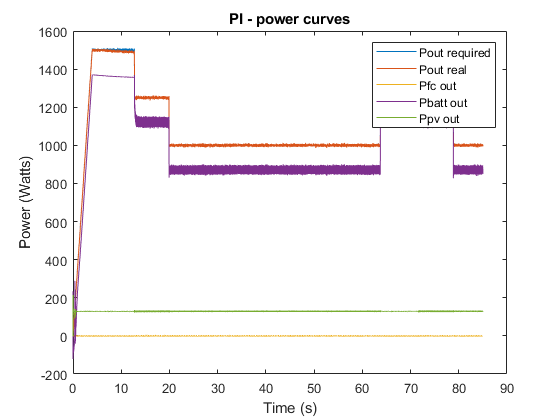

tic
power_curve(PI,'PI');

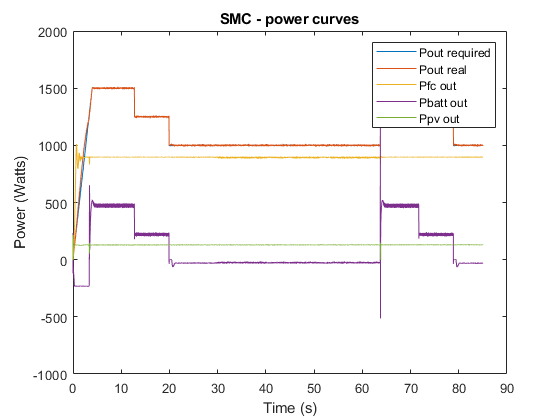

power_curve(SMC,'SMC');

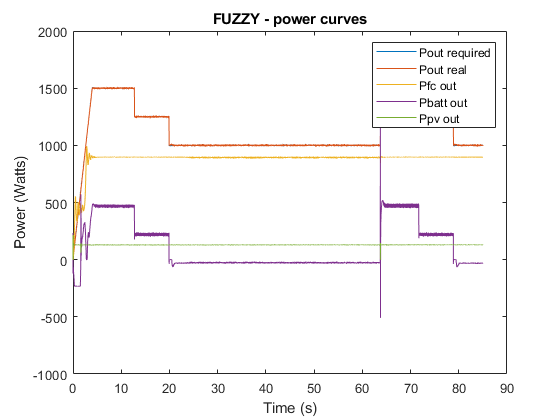

power_curve(FUZZY,'FUZZY');

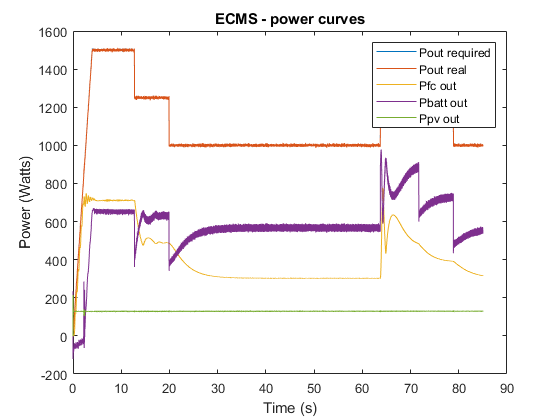

power_curve(ECMS,'ECMS');

toc

Elapsed time is 5.805216 seconds.


## SOC

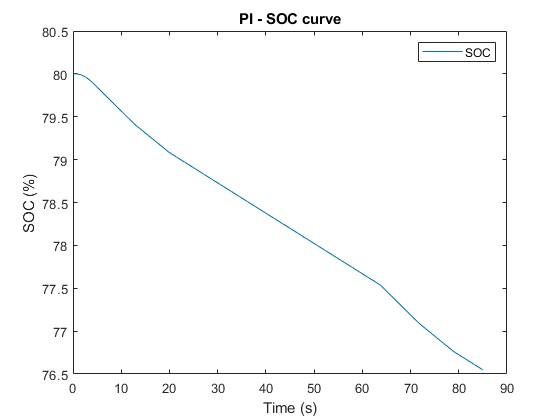

tic
soc_curve(PI,'PI');

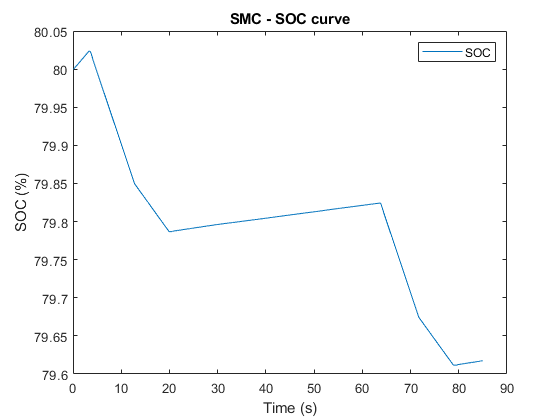

soc_curve(SMC,'SMC');

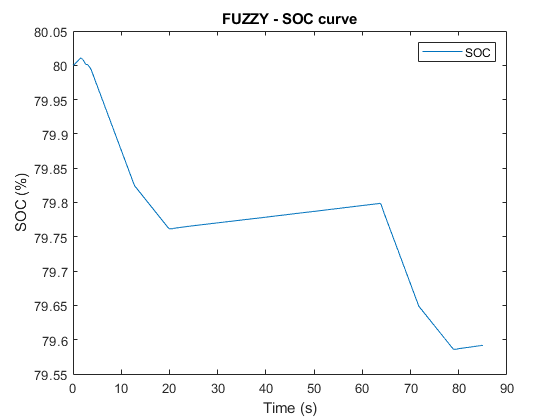

soc_curve(FUZZY,'FUZZY');

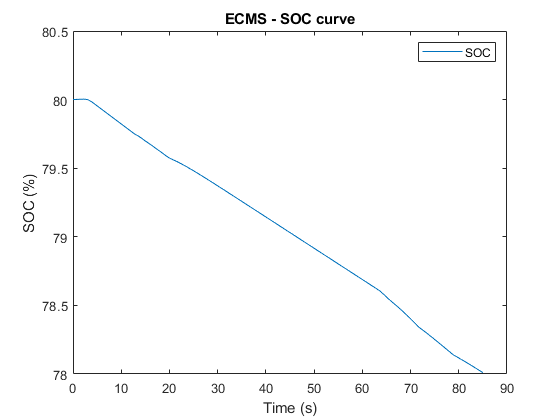

soc_curve(ECMS,'ECMS');

toc

Elapsed time is 2.688671 seconds.


# Comparison data

## Power mean value

tic
m_power = mean_power(EMS_sim);
row_names = {'Pfc_in','Pfc_out','Pbatt_in','Pbatt_out','Ppv_in','Ppv_out','Psc'};
column_names = {'PI','SMC','FUZZY','ECMS'};
table_power = array2table(m_power','RowNames',row_names,'VariableNames',column_names)

table_power = 7×4 table
                    PI        SMC      FUZZY      ECMS 
                 ________    ______    ______    ______

    Pfc_in       0.061067    993.39    980.95    464.04
    Pfc_out      -0.98963    891.25     880.1    416.29
    Pbatt_in       1109.3    125.07    133.48    646.85
    Pbatt_out      997.94    107.91    116.44    581.84
    Ppv_in         144.57    144.66    144.73    144.72
    Ppv_out        129.04    129.12    129.18    129.17
    Psc            1.3164    2.9249     3.238    1.5634


toc

Elapsed time is 0.132964 seconds.


## Error mean value

tic
m_error = mean_error(EMS_sim);
row_names = {'RMSE P','RMSE V','MEP (%)','MEV (%)'};
column_names = {'PI','SMC','FUZZY','ECMS'};
table_power = array2table(m_error','RowNames',row_names,'VariableNames',column_names)

table_power = 4×4 table
                 PI         SMC       FUZZY        ECMS  
               _______    _______    ________    ________

    RMSE P      4.0411      14.77      1.6627      0.9068
    RMSE V     0.10002    0.76379    0.099511    0.028499
    MEP (%)    0.15312    0.40592    0.061719    0.042409
    MEV (%)    0.07665    0.19739    0.030805    0.021209


toc

Elapsed time is 0.273053 seconds.


## Consumption / SOC / SOH / age

tic
m_consu = consumption(EMS_sim);
row_names = {'H2 cons','SOC','SOH','age'};
column_names = {'PI','SMC','FUZZY','ECMS'};
table_consu = array2table(m_consu','RowNames',row_names,'VariableNames',column_names)

table_consu = 4×4 table
                   PI          SMC       FUZZY      ECMS  
               __________    _______    _______    _______

    H2 cons    8.0729e-05     1.3656     1.3457    0.53109
    SOC            76.548     79.617     79.592      78.01
    SOH           0.96548    0.99617    0.99592     0.9801
    age                 1    0.99906    0.99907          1


toc

Elapsed time is 0.314419 seconds.
